## Evaluating Slope Performance

### 20 MHz BW Chirps

slopes_to_test = 0.46:0.02:1.24;
slope_errors = zeros(1,size(slopes_to_test,2));
chirp_duration_errors = zeros(1,size(slopes_to_test,2));

parfor i = 1:size(slopes_to_test,2)
    cycle_period_us = 47.32;
    slope_MHz_us = slopes_to_test(i);
    BW_MHz = 20;
    num_chirps = 32;
    [average_slope,average_chirp_duration] = compute_sensed_values(cycle_period_us,slope_MHz_us,BW_MHz,num_chirps);
    slope_errors(i) = average_slope - slope_MHz_us;
    chirp_duration_errors(i) = average_chirp_duration -cycle_period_us;
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


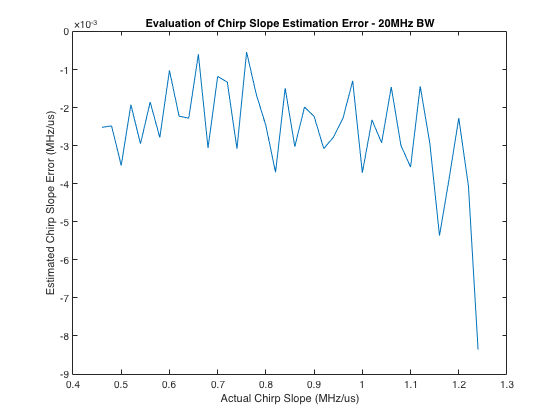


plot(slopes_to_test,slope_errors);
title_str = sprintf('Evaluation of Chirp Slope Estimation Error - 20MHz BW');
title(title_str);
xlabel('Actual Chirp Slope (MHz/us)');
ylabel('Estimated Chirp Slope Error (MHz/us)');

### 10 MHz BW Chirps

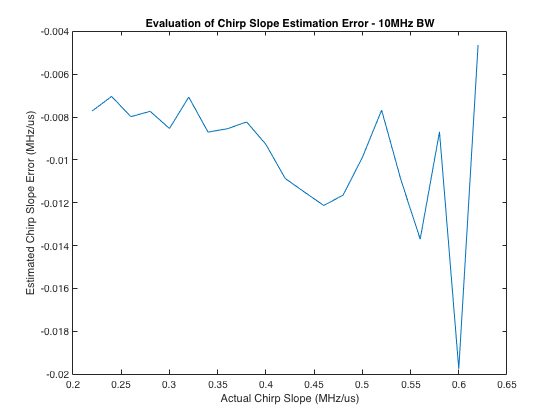

slopes_to_test = 0.22:0.02:0.62;
slope_errors = zeros(1,size(slopes_to_test,2));
chirp_duration_errors = zeros(1,size(slopes_to_test,2));

parfor i = 1:size(slopes_to_test,2)
    cycle_period_us = 47.32;
    slope_MHz_us = slopes_to_test(i);
    BW_MHz = 10;
    num_chirps = 32;
    [average_slope,average_chirp_duration] = compute_sensed_values(cycle_period_us,slope_MHz_us,BW_MHz,num_chirps);
    slope_errors(i) = average_slope - slope_MHz_us;
    chirp_duration_errors(i) = average_chirp_duration -cycle_period_us;
end

plot(slopes_to_test,slope_errors);
title_str = sprintf('Evaluation of Chirp Slope Estimation Error - 10MHz BW');
title(title_str);
xlabel('Actual Chirp Slope (MHz/us)');
ylabel('Estimated Chirp Slope Error (MHz/us)');

## Evaluating Chirp Period Performance

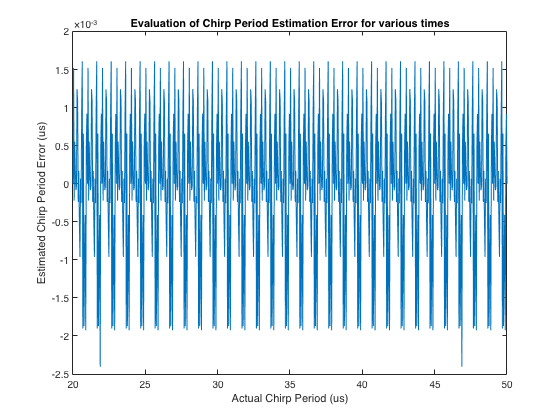

times_to_test = 20:0.04:50;
slope_errors = zeros(1,size(times_to_test,2));
chirp_duration_errors = zeros(1,size(times_to_test,2));

parfor i = 1:size(times_to_test,2)
    cycle_period_us = times_to_test(i);
    slope_MHz_us = 1.2;
    BW_MHz = 20;
    num_chirps = 128;
    [average_slope,average_chirp_duration] = compute_sensed_values(cycle_period_us,slope_MHz_us,BW_MHz,num_chirps);
    slope_errors(i) = average_slope - slope_MHz_us;
    chirp_duration_errors(i) = average_chirp_duration -cycle_period_us;
end

plot(times_to_test,chirp_duration_errors);
title_str = sprintf('Evaluation of Chirp Period Estimation Error for various times');
title(title_str);
xlabel('Actual Chirp Period (us)');
ylabel('Estimated Chirp Period Error (us)');

function [average_slope,average_chirp_duration] = compute_sensed_values(cycle_period_us,slope_MHz_us,BW_MHz,num_chirps)
    %configure chirp parameters
    chirp_params.cycle_period_us = cycle_period_us;
    chirp_params.slope_MHz_us = slope_MHz_us;
    chirp_params.BW_MHz = BW_MHz;                   %BW will be close to, but not exactly this
    chirp_params.FMCW_sample_rate_Msps = 50;
    chirp_params.ramp_end_time_us = ceil(chirp_params.BW_MHz / chirp_params.slope_MHz_us);
    chirp_params.BW_MHz = chirp_params.ramp_end_time_us * chirp_params.slope_MHz_us;
    chirp_params.idle_time_us = chirp_params.cycle_period_us - chirp_params.ramp_end_time_us;
    chirp_params.num_samples_idle_time = int32(chirp_params.idle_time_us * chirp_params.FMCW_sample_rate_Msps);
    
    %configure frame parameters
    frame_params.num_chirps = num_chirps;
    
    %configure waveform parameters
    waveform_params.sample_rate_Hz = chirp_params.FMCW_sample_rate_Msps * 1e6;
    waveform_params.sweep_time_s = chirp_params.ramp_end_time_us * 1e-6;
    waveform_params.sweep_BW_Hz = chirp_params.BW_MHz * 1e6;
    waveform_params.sweep_interval = 'Positive';
    waveform_params.sweep_direction = 'Up';
    waveform_params.output_format = 'Sweeps';
    waveform_params.num_sweeps = 1;
    
    waveform = phased.FMCWWaveform("SampleRate",waveform_params.sample_rate_Hz, ...
                                    'SweepTime', waveform_params.sweep_time_s, ...
                                    'SweepBandwidth', waveform_params.sweep_BW_Hz, ...
                                    'SweepDirection', waveform_params.sweep_direction, ...
                                    'SweepInterval', waveform_params.sweep_interval, ...
                                    'OutputFormat',waveform_params.output_format, ...
                                    'NumSweeps',waveform_params.num_sweeps);
    
    chirp = [zeros(chirp_params.num_samples_idle_time,1); waveform()];
    
    spectogram_params.fft_size = 32;
    %for use in the simulink model
    fft_size = spectogram_params.fft_size;
    spectogram_params.freq_sampling_period_us = 1; %sample frequency every 1us
    spectogram_params.num_samples_per_sampling_window = spectogram_params.freq_sampling_period_us * chirp_params.FMCW_sample_rate_Msps;
    spectogram_params.num_freq_spectrum_samples_per_spectogram = 50;
    spectogram_params.num_ADC_samples_per_spectogram = spectogram_params.num_freq_spectrum_samples_per_spectogram * spectogram_params.num_samples_per_sampling_window;
    
    %compute the window to be used when generating the spectogram
    window = hann(spectogram_params.fft_size);
    
    %initialize array to track captured chirps
    chirps_to_capture = 128;        %this will be the maximum number of chirps captured when computing the average chirp duration
    num_captured_chirps = 0;
    captured_chirps = zeros(chirps_to_capture, 2);
    average_chirp_duration = 20;
    average_slope = 0;
    
    %initialize array to hold the previously measured spectrum
    previous_spectogram_points = [];
    
    %initialize counter to keep track of how many full iterations of the while loop
    %have occurred
    while_loop_count = 0;
    
    %first compute the sampled chirp that the sensing system would receive
    
    %create additional counting variables to aid in the construction of the
    %received chirp
    chirp_sample_index = 1;
    max_chirp_sample_index = size(chirp,1);
    chirp_samples_left = max_chirp_sample_index - 1;
     
    received_sample_index = 1;
    max_received_sample_index = spectogram_params.num_ADC_samples_per_spectogram;
    received_samples_left = max_received_sample_index - 1;
    
    num_chirps_to_compute = frame_params.num_chirps;
    chirp_count = 0;
    while chirp_count < num_chirps_to_compute
    
        received_signal = zeros(spectogram_params.num_ADC_samples_per_spectogram,1);
        received_signal_assembled = 0;
    
        while ~received_signal_assembled
            if chirp_count >= num_chirps_to_compute
                %if this is the last chirp in the frame, fill in the remaining
                % part of the received signal with zeros
                points_to_insert = received_samples_left;
                
                received_signal(received_sample_index:received_sample_index + points_to_insert) = zeros(points_to_insert + 1,1);
                
                received_sample_index = 1;
                received_samples_left = max_received_sample_index - 1;
                received_signal_assembled = 1;
            elseif received_samples_left >= chirp_samples_left
                points_to_insert = chirp_samples_left;
                received_signal(received_sample_index:received_sample_index + points_to_insert) = chirp(chirp_sample_index:chirp_sample_index + points_to_insert);
                
                chirp_sample_index = 1;
                chirp_samples_left = max_chirp_sample_index - 1;
                chirp_count = chirp_count + 1;
            
                received_sample_index = received_sample_index + points_to_insert + 1;
                received_samples_left = max_received_sample_index - received_sample_index;
    
                if received_samples_left < 0
                    received_sample_index = 1;
                    received_samples_left = max_received_sample_index - 1;
                    received_signal_assembled = 1;
                end
                
            else
                points_to_insert = received_samples_left;
                received_signal(received_sample_index:received_sample_index + points_to_insert) = chirp(chirp_sample_index:chirp_sample_index + points_to_insert);
            
                chirp_sample_index = chirp_sample_index + points_to_insert + 1;
                chirp_samples_left = max_chirp_sample_index - chirp_sample_index;
            
                received_sample_index = 1;
                received_samples_left = max_received_sample_index - 1;
                received_signal_assembled = 1;
            end
        end
    
        reshaped_signal = reshape(received_signal,spectogram_params.num_freq_spectrum_samples_per_spectogram,[]);
        
        %next, shave off the last few samples so that we get the desired fft size
        reshaped_signal_for_fft = reshaped_signal(1:spectogram_params.fft_size,:);
        
        %window the signal
        windowed_signal = reshaped_signal_for_fft .* window;
        
        %perform an fft
        generated_spectogram = fft(windowed_signal);
        
        %clip off the negative frequencies;
        generated_spectogram = generated_spectogram(1:spectogram_params.fft_size/2,:);
        half_fft_size = spectogram_params.fft_size/2;
        
        %plot the spectogram to confirm correct implementation
        plot_params.max_freq = chirp_params.FMCW_sample_rate_Msps/2;
        plot_params.freq_resolution = chirp_params.FMCW_sample_rate_Msps/spectogram_params.fft_size;
        plot_params.frequencies = 0:plot_params.freq_resolution:plot_params.max_freq - plot_params.freq_resolution;
        plot_params.times = 0: spectogram_params.freq_sampling_period_us : spectogram_params.num_freq_spectrum_samples_per_spectogram - spectogram_params.freq_sampling_period_us;
            
        peak_detection_params.threshold = 5;
        peak_detection_params.numPeaks = 2;
        spectogram_points = [];  %array to hold the time, freq locations of valid spectogram points
        
        for i = 1:size(generated_spectogram,2)
            [peaks,locations] = findpeaks(abs(generated_spectogram(:,i)),"NPeaks",peak_detection_params.numPeaks);
            locations = locations(peaks > peak_detection_params.threshold);
            if ~isempty(locations)
                locations = [locations.'; i * ones(1,size(locations,1))];
                spectogram_points = [spectogram_points,locations];
            end
        end
        
        %perform clustering on the new spectogram combined with the previous
        %one
        if ~isempty(spectogram_points)
            combined_spectogram = [previous_spectogram_points,spectogram_points + [0;spectogram_params.num_freq_spectrum_samples_per_spectogram]];
        else
            combined_spectogram = previous_spectogram_points;
        end
        previous_spectogram_points = spectogram_points;
        [idx,corepts] = dbscan((combined_spectogram).',5,2);
        
        %compute new times for the combined_spectogram
        plot_params.combined_spectogram_times = 0: spectogram_params.freq_sampling_period_us : 2 * spectogram_params.num_freq_spectrum_samples_per_spectogram - spectogram_params.freq_sampling_period_us;
    
        %plot the detected points to confirm that they align
        detected_frequencies = plot_params.frequencies(combined_spectogram(1,:));
        detected_times = plot_params.combined_spectogram_times(combined_spectogram(2,:));
    
        %solve for the linear equation for each cluster provided there are enough
        %points
        max_num_clusters = 10;
        threshold = 15;
        detected_chirps = zeros(max(idx),2);
        for cluster_id = 1:max(idx)
            %solve for linear model using linear algrebra
            %y is frequencies, x is time
            if sum(idx == cluster_id) > threshold
                X = [ones(size(detected_times(idx == cluster_id),2),1),detected_times(idx == cluster_id).'];
                Y = detected_frequencies(idx == cluster_id).';
                B = inv(X.' * X) * X.' * Y;
                detected_chirps(cluster_id,1:2) = [-B(1)/B(2),B(2)];
                slope = detected_chirps(cluster_id,2);
                intercept = detected_chirps(cluster_id,1);
            end
        end
    
        %Now, we experiment with only taking 15 points to determine the slope and
        %intercept
        num_points_for_linearizing = 15;
        detected_chirps_simplified = zeros(max(idx),2);
        for cluster_id = 1:max(idx)
            if sum(idx == cluster_id) >= num_points_for_linearizing
                cluster_times = detected_times(idx == cluster_id);
                cluster_freqs = detected_frequencies(idx == cluster_id);
                X_simplified = [ones(num_points_for_linearizing,1),cluster_times(1:num_points_for_linearizing).'];
                Y_simplified = cluster_freqs(1:num_points_for_linearizing).';
                B_simplified = inv(X_simplified.' * X_simplified) * X_simplified.' * Y_simplified;
                detected_chirps_simplified(cluster_id,1:2) = [-B_simplified(1)/B_simplified(2),B_simplified(2)];
                slope_simplified = detected_chirps_simplified(cluster_id,2);
                intercept_simplified = detected_chirps_simplified(cluster_id,1);
            end
        end
        %detected_chirps_simplified - detected_chirps;
        %shows that decreasing the number of points affected the computed intercept
        %point
    
        detected_chirps = detected_chirps + [spectogram_params.num_freq_spectrum_samples_per_spectogram * (while_loop_count - 1), 0];
        for i = 1:size(detected_chirps,1)
            if detected_chirps(i,2) ~= 0 && num_captured_chirps < chirps_to_capture
                if num_captured_chirps == 0
                    captured_chirps(1,:) = detected_chirps(i,:);
                    num_captured_chirps = num_captured_chirps + 1;
                elseif all(abs(captured_chirps - detected_chirps(i,1)) > average_chirp_duration / 2,'all')
                    captured_chirps(num_captured_chirps + 1,:) = detected_chirps(i,:);
                    num_captured_chirps = num_captured_chirps + 1;
                end
                average_slope = sum(captured_chirps(1:num_captured_chirps,2))/ double(num_captured_chirps);
                if num_captured_chirps >= 2
                    average_chirp_duration = (captured_chirps(num_captured_chirps,1) - captured_chirps(1,1))/double(num_captured_chirps - 1);
                end
                
            end
        end
    
        while_loop_count = while_loop_count + 1;
    end
end
  